# `Digital Phase Locked Loop tone tracking `

## `Overview`

This model demonstrates a digital Phase-Locked Loop (PLL) designed to track the phase of a sinusoidal signal. The received input consists of two sinusoidal components with added noise. A user-adjustable dial is provided to set the frequency of a local oscillator, allowing for a ±0.5% frequency offset.

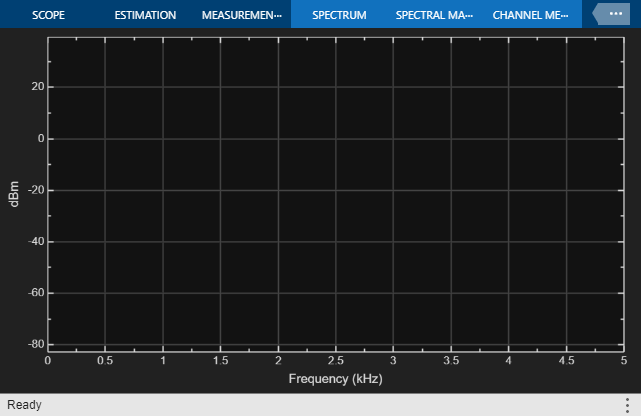

model = 'digitalPLL_toneTrack';
open(model)

Note that the model is initialized in the postLoadFcn call back -- right click on the canvas ->Model Properties -> PostLoadFcn; 

Zooming in to view the spectrum analyzer at around 1kHz we can see the received signal (yellow Rx) and the NCO output (Blue NCO out) at the beginning when the two peaks are at different frequencies.

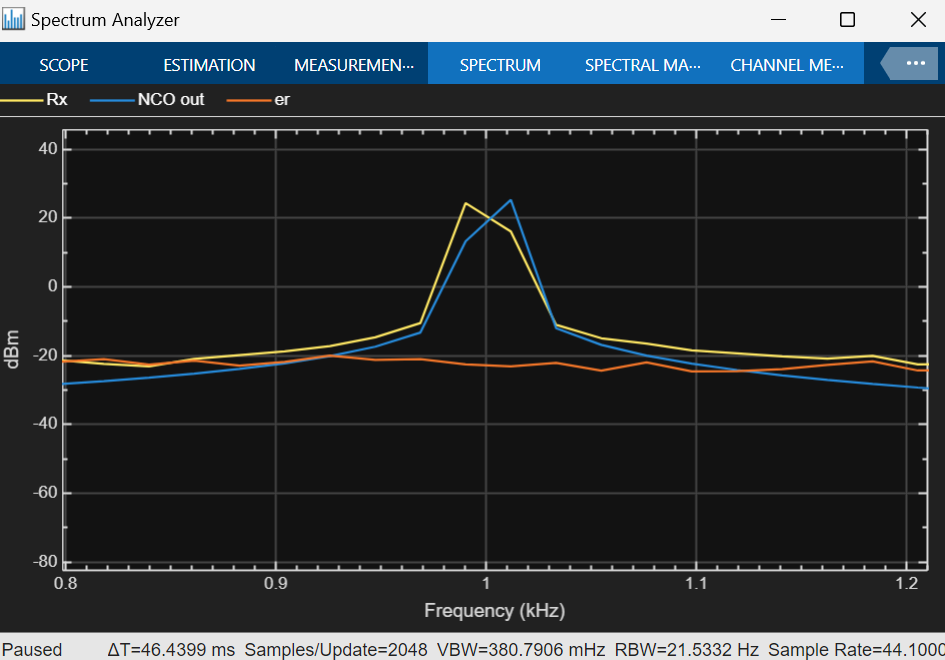

After running for a while the two peaks will be aligned, the frequencies are the same.

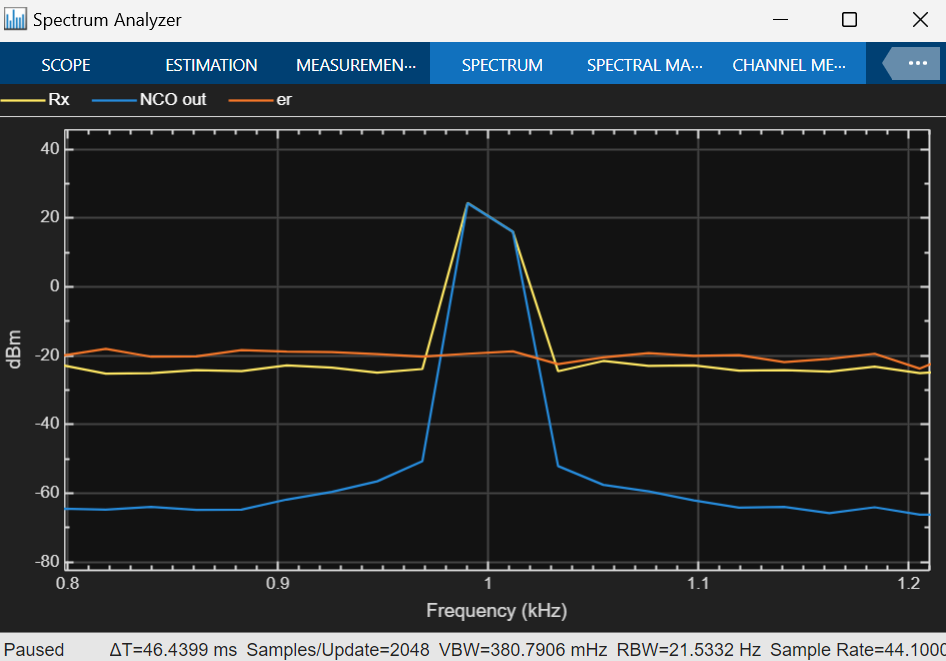

In the time scope we can see that the phase is synchronzied.

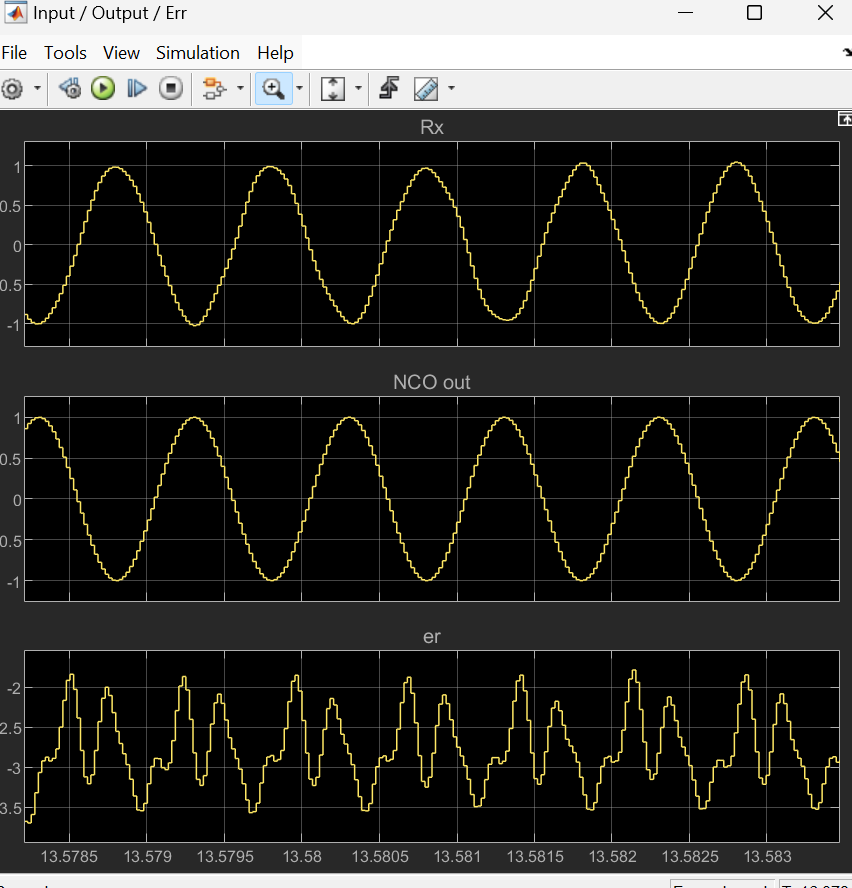

## `Anatomy of a Phased Locked Loop`

A simple analog phased locked loop as described in wikipedia consists of a phase comparator, a loop filter and a voltage controlled oscillator.  The general idea is to first detect the 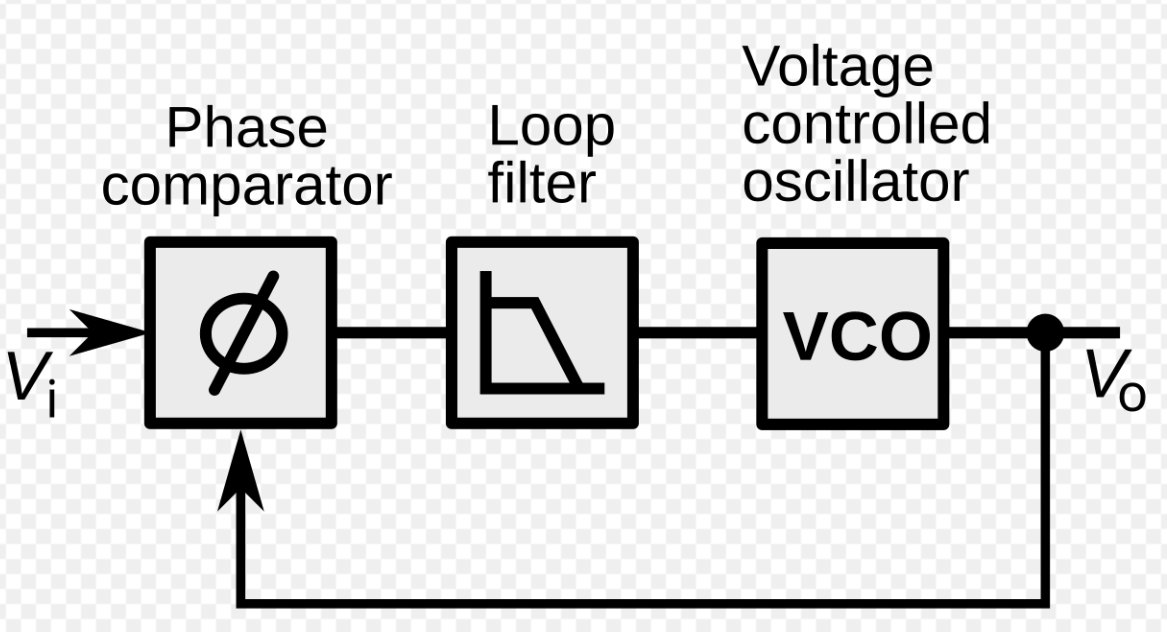

phase difference between the local oscillator and the incoming signal.  The phase difference are then passed into a filter that smooths this error signal.  Finally, this smoothed error signal is then passed to an oscillator to generate a clock that is closer to the incoming signal by compensating for the error.  In this example we will be implementing an all digital PLL.  The PLL implementation includes a sinusoidal phase detector, a lead-lag (first order) loop filter, and a numerical controlled oscillator (NCO). It is a second-order phase-locked loop.

### Sinusoidal Phase Detector

In our model, the incoming signal and the locally generated sinusoids are first converted to be complex valued through Hilbert filters.  

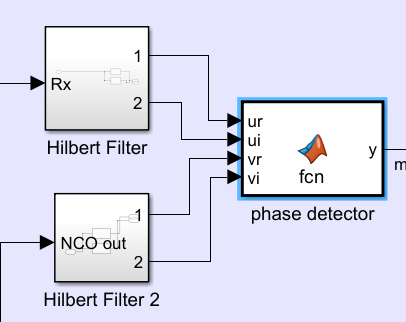

The phase difference between two complex sinusoids can are obtained through a multiplication operation. Taking the imaginary part of the multiplied output would be a representation of the phase difference.  


$$diff =  imag( \, incoming * local \, )\\
incoming =  e^{jw_1t+\phi_1}  \\
local = e^{-jw_2t-\phi_2}  \\
diff = imag (e^{j(w_1t-w_2t+\phi_1-\phi_2)}) \\
diff = sin({w_1t-w_2t+\phi_1-\phi_2}) \\
diff = sin ( \phi_e)$$


In addition, we could obtain better performance if a gain factor of 2 is applied to the phase difference.  


$$diff2 = sin( \, 2 \phi_e  \,) $$


Using the identity:


$$sin( 2 \theta ) = 2 * sin(\theta) * cos(\theta)$$


We have:


$$diff2 = 2* imag (e^{j(w_1t-w_2t+\phi_1-\phi_2)}) * real (e^{j(w_1t-w_2t+\phi_1-\phi_2)})
$$


With,


$$u = incoming \\
v = local  
$$


We have,


$$diff2 = 2 * (real(u)*imag(v)-imag(u)*real(v) )*(real(u)*real(v)+imag(u)*imag(v))$$


In MATLAB,

y = 2*(ur.*vi-ui.*vr).*(ur.*vr+ui.*vi);

### Loop filter

The lead-lag loop filter implemented using op-amp in analog circuitry is shown below [1].

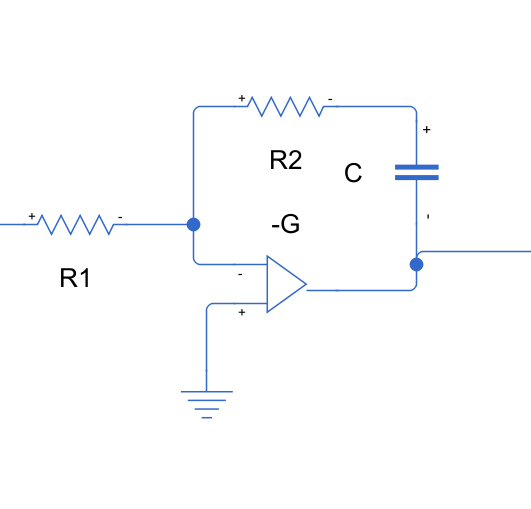

The filter equation is:


$$F(s) = \frac{1+\tau_2s}{\tau_1 s}$$



$$\tau_1 = R_1C \\
\tau_2 = R_2C$$


The eqivalent analog circuit is:

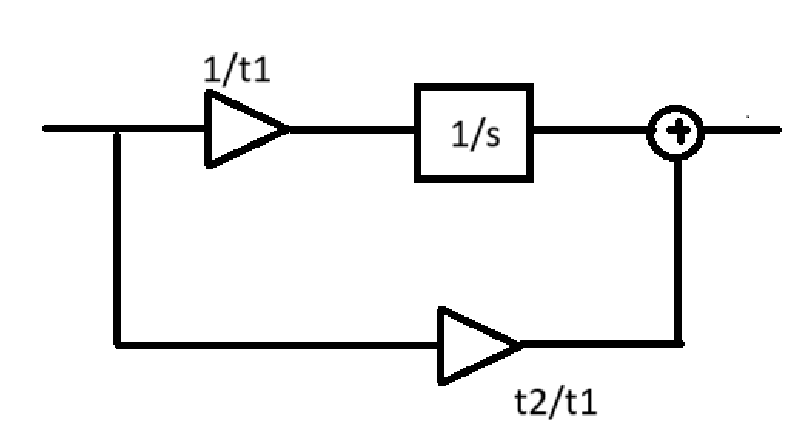

Replacing the integrator with an accumulator, we have the below digital circuit:

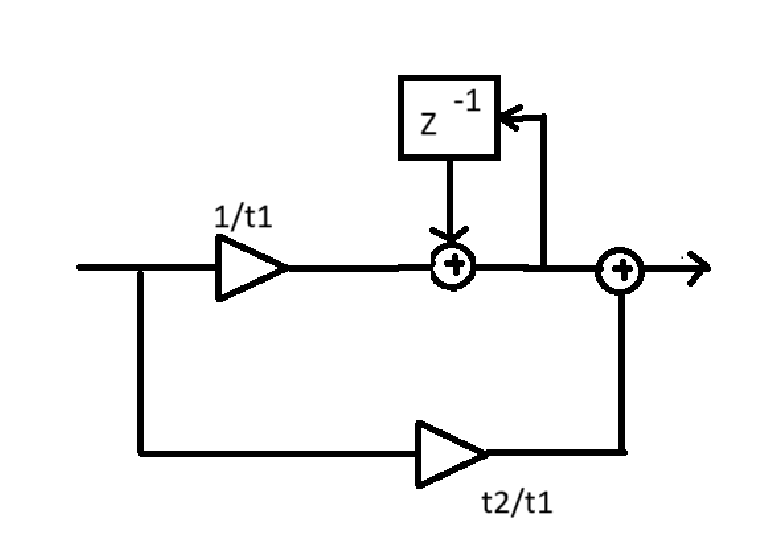


$$H(z) = \frac{T }{\tau_1 \, (1-z^{-1})}+ \frac{\tau_2}{\tau_1}$$



$$T = \frac{1}{fs} \,  , \, \,
K1 = \frac{T}{\tau_1}  \\
K2 = \frac{\tau_2}{\tau_1}$$


In MATLAB,

 yy = k1 *x + memy;

memy = x;

y = yy + k2 *x;

For critical damping ($\zeta = 1$), we can set

k1 = k2*k2 / 4; 

### Numerical Controlled Oscillator

Notice that all parts of the system is operating in frames except this section.  The parameter samples per frame (spf) is applied to other sections.  Thus, there is one frame of data being generated at the output of the loop filter.  

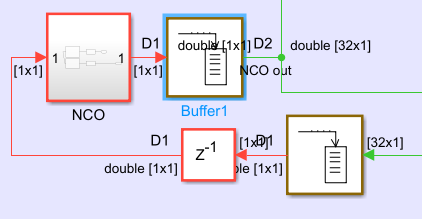

If spf = 32 then there will be 32 samples being passed to the NCO block.  Generally, a longer delay in the feedback loop would make the overall system easier to be unstable. Nevertheless, most digital systems are processed in frames and not sample-by-sample.  Since this is an all digital system a digital NCO is used.  The NCO used here accepts a fixed-point (not floating-point) input.  Thus, the adjustment from the loop filter will need to be scaled to fixed-point (16-bit) and be consumed sample-by-sample.

At the NCO block, the local oscillator frequency is set in the variable ncoclk.  This frequency value is used to generate a constant phase.  In radians and quantized to 16 bits we have:

constPhase = int16(ncoclk*(2^16)/fs);